clear; close all;

J = [0 -1 0; 1 0 0; 0 0 0];
% w = 2*pi*60;
format short

syms t;
syms LA LB theta_r Lsf w theta_m;


L_diag = @(phase) LA+LB*cos(2*(theta_r+phase));
L_not_diag = @(phase) -1/2*LA+LB*cos(2*(theta_r+phase));

a = 2*pi/3;

Lss = [L_diag(0) L_not_diag(a) L_not_diag(-a);
      L_not_diag(a) L_diag(-a) L_not_diag(0);
      L_not_diag(-a) L_not_diag(0) L_diag(a);];
Lfs = Lsf*[cos(theta_r); cos(theta_r-a); cos(theta_r+a);];

% rotor reference
T = [cos(theta_m)  cos(theta_m-a)  cos(theta_m+a);
    -sin(theta_m) -sin(theta_m-a) -sin(theta_m+a);
    1/2            1/2         1/2;] *2/3;

% station reference
T0 = [cos(0)  cos(-a)  cos(a);
    -sin(0) -sin(-a) -sin(a);
    1/2            1/2         1/2;] *2/3;

Ldqss = simplify( T0 * Lss * inv(T0) );
Ldqss = Ldqss(1:2, 1:2)

$$Ldqss = \left(\begin{array}{cc} 30\,\cos\left(2\,\theta_{r}\right)+\frac{15}{2} & 30\,\sin\left(2\,\theta_{r}\right)\\ 30\,\sin\left(2\,\theta_{r}\right) & \frac{15}{2}-30\,\cos\left(2\,\theta_{r}\right) \end{array}\right)$$

Ldqse = simplify( T*Lss*inv(T) )

$$Ldqse = \left(\begin{array}{ccc} 30\,\cos\left(2\,\theta_{m}-2\,\theta_{r}\right)+\frac{15}{2} & -30\,\sin\left(2\,\theta_{m}-2\,\theta_{r}\right) & 0\\ -30\,\sin\left(2\,\theta_{m}-2\,\theta_{r}\right) & \frac{15}{2}-30\,\cos\left(2\,\theta_{m}-2\,\theta_{r}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

Ldqse = Ldqse(1:2, 1:2)

$$Ldqse = \left(\begin{array}{cc} 30\,\cos\left(2\,\theta_{m}-2\,\theta_{r}\right)+\frac{15}{2} & -30\,\sin\left(2\,\theta_{m}-2\,\theta_{r}\right)\\ -30\,\sin\left(2\,\theta_{m}-2\,\theta_{r}\right) & \frac{15}{2}-30\,\cos\left(2\,\theta_{m}-2\,\theta_{r}\right) \end{array}\right)$$


det(Ldqss);
subs(ans, theta_r, 0)

$$ans = -\frac{3375}{4}$$


det(Ldqse);
subs(ans, theta_r, 0)

$$ans = -900\,{\cos\left(2\,\theta_{m}\right)}^{2}-900\,{\sin\left(2\,\theta_{m}\right)}^{2}+\frac{225}{4}$$

kk = subs(ans, theta_m, -pi/2:pi/10:pi/2);
kk = double(kk)

kk =  -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500 -843.7500


여기서 Ldqse(1,1)은 Lds, Ldqse(2,2)는 Lqs라고 하자.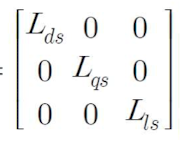 

syms Lds Lqs
Ldqse = diag([Lds Lqs 0])

$$Ldqse = \left(\begin{array}{ccc} \mathrm{Lds} & 0 & 0\\ 0 & \mathrm{Lqs} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Lfw = simplify( T*Lfs )

$$Lfw = \left(\begin{array}{c} \mathrm{Lsf}\,\cos\left(\theta_{m}-\theta_{r}\right)\\ -\mathrm{Lsf}\,\sin\left(\theta_{m}-\theta_{r}\right)\\ 0 \end{array}\right)$$

syms id iq
I_dq = [id; iq; 0]; % dqn current

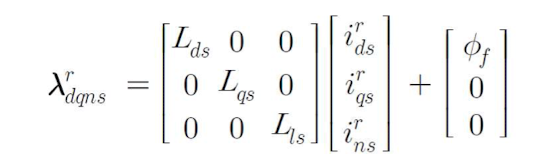

lambda_dq = Ldqse*I_dq + Lfw; % 문제3.5 SynRM은 Lfw =0, 즉 계자 플럭스가 0이다.

V_dq = w*J*lambda_dq % 정상상태라고 가정. #미분항 제외 #저항은 매우 작다

$$V\_dq = \left(\begin{array}{c} -w\,\left(\mathrm{Lqs}\,\mathrm{iq}-\mathrm{Lsf}\,\sin\left(\theta_{m}-\theta_{r}\right)\right)\\ w\,\left(\mathrm{Lds}\,\text{id}+\mathrm{Lsf}\,\cos\left(\theta_{m}-\theta_{r}\right)\right)\\ 0 \end{array}\right)$$

V_abc = simplify( inv(T)*V_dq )

$$V\_abc = \begin{array}{l} \left(\begin{array}{c} -w\,\left(\mathrm{Lsf}\,\sin\left(\theta_{r}\right)+\sigma_{2}+\sigma_{1}\right)\\ \frac{w\,\left(\mathrm{Lsf}\,\sin\left(\theta_{r}\right)+\sqrt{3}\,\mathrm{Lsf}\,\cos\left(\theta_{r}\right)+\sigma_{2}+\sigma_{1}+\sigma_{3}-\sigma_{4}\right)}{2}\\ \frac{w\,\left(\mathrm{Lsf}\,\sin\left(\theta_{r}\right)-\sqrt{3}\,\mathrm{Lsf}\,\cos\left(\theta_{r}\right)+\sigma_{2}+\sigma_{1}-\sigma_{3}+\sigma_{4}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Lds}\,\text{id}\,\sin\left(\theta_{m}\right)\\ \sigma_{2}=\mathrm{Lqs}\,\mathrm{iq}\,\cos\left(\theta_{m}\right)\\ \sigma_{3}=\sqrt{3}\,\mathrm{Lds}\,\text{id}\,\cos\left(\theta_{m}\right)\\ \sigma_{4}=\sqrt{3}\,\mathrm{Lqs}\,\mathrm{iq}\,\sin\left(\theta_{m}\right) \end{array}$$

syms PP;
Torque = simplify( 3/2* PP/2*cross(lambda_dq, I_dq) )

$$Torque = \left(\begin{array}{c} 0\\ 0\\ -\frac{3\,\mathrm{PP}\,\left(\text{id}\,\left(\mathrm{Lqs}\,\mathrm{iq}-\mathrm{Lsf}\,\sin\left(\theta_{m}-\theta_{r}\right)\right)-\mathrm{iq}\,\left(\mathrm{Lds}\,\text{id}+\mathrm{Lsf}\,\cos\left(\theta_{m}-\theta_{r}\right)\right)\right)}{4} \end{array}\right)$$